# Test Ho-Kalman Algorithm

clear all; close all; clc;

## FLAGS

### HK Rank

- Using Rank, r = rank(S)

- All States from Hankel

- Number of States

- Number of short dynamics States

FLAG.HK_rank = 1;

### Adjust HK Input Magnitude

- No magnitude adjustment

- Simple order of magnitude % Not implemented

- Overall change is 1

FLAG.HK_AdjustMag = 3;

### Others

FLAG.Use_t_minus = 0; % 1 if the impulse occurs before t_impulse; 0 if impulse occurs after
FLAG.Use_Ind_ROM = 0; % 1 if using individual ROMs, 0 if using a combined ROM

## Initial Parameters

Ts          = 1; % [s], Sampling Rate
TsMultiple  = 5; % Times in between samples
TsSim       = Ts/TsMultiple; % Simulate with finer t_vec
N_steps_min = 50; % Minimum number of steps to take

## Create CT State Space System

### A Matrix

N_dominate_dynam = 5; 
dominate_min = -2;
dominate_max = -1;
dominate_eig = logspace(dominate_min,dominate_max,N_dominate_dynam);

% N_nondom_dynam = 10-N_dominate_dynam;
N_nondom_dynam = 1;
%N_nondom_dynam = 100;
nondom_min = 1;
nondom_max = 2;
nondom_eig = logspace(nondom_min,nondom_max,N_nondom_dynam);

Aeig = -1*[dominate_eig , nondom_eig];
A = diag(Aeig);

### B Matrix

% B = zeros(length(A),1); B(1) = 1;
B = ones(length(A),1);

### C Matrix

C = eye(length(A));
%C = zeros(length(A)); C(1,1) = 1;

### D Matrix

D = zeros(length(C),1);

### Create SS objects

sys_CT = ss(A,B,C,D);
sys_DT = c2d(sys_CT,Ts);

### Determine Eigenvalues of System

[eig_vec, eig_val] = eig(sys_CT.A);
eig_val

eig_val =  -100.0000         0         0         0         0         0
         0   -0.1000         0         0         0         0
         0         0   -0.0562         0         0         0
         0         0         0   -0.0316         0         0
         0         0         0         0   -0.0178         0
         0         0         0         0         0   -0.0100


[U,S,V] = svd(A);
S

S =   100.0000         0         0         0         0         0
         0    0.1000         0         0         0         0
         0         0    0.0562         0         0         0
         0         0         0    0.0316         0         0
         0         0         0         0    0.0178         0
         0         0         0         0         0    0.0100


[eig_vec_DT, eig_val_DT] = eig(sys_DT.A);
eig_val_DT

eig_val_DT =     0.0000         0         0         0         0         0
         0    0.9048         0         0         0         0
         0         0    0.9453         0         0         0
         0         0         0    0.9689         0         0
         0         0         0         0    0.9824         0
         0         0         0         0         0    0.9900


[U_DT,S_DT,V_DT] = svd(sys_DT.A);
S_DT

S_DT =     0.9900         0         0         0         0         0
         0    0.9824         0         0         0         0
         0         0    0.9689         0         0         0
         0         0         0    0.9453         0         0
         0         0         0         0    0.9048         0
         0         0         0         0         0    0.0000


## Create Time Vectors

if 2*length(A) < N_steps_min
    t_final = N_steps_min * Ts;
else
    t_final = 2*length(A)*Ts;
end

t_vec_ode = 0:TsSim:t_final;
t_vec_DT  = 0:Ts:t_final;

## Create Impulse Current Profile

### Get Profile for ODE simulation

current = zeros(size(t_vec_ode));
if FLAG.Use_t_minus
    idx = TsMultiple+1:1:2*TsMultiple;
else
    idx = TsMultiple+2:1:2*TsMultiple+1;
end
current(idx) = ones(size(idx));

if FLAG.Use_t_minus
    ImpulseCurrentProfile.t = [t_vec_ode(1:TsMultiple) , Ts-Ts/50 , t_vec_ode(TsMultiple+1:2*TsMultiple) , 2*Ts-Ts/50 , t_vec_ode(2*TsMultiple+1:end)]';
    ImpulseCurrentProfile.u = [  current(1:TsMultiple) , 0        ,   current(TsMultiple+1:2*TsMultiple) , 1          ,   current(2*TsMultiple+1:end)]';
else
    ImpulseCurrentProfile.t = [t_vec_ode(1:TsMultiple+1) , Ts+Ts/50 , t_vec_ode(TsMultiple+2:2*TsMultiple+1) , 2*Ts+Ts/50 , t_vec_ode(2*TsMultiple+2:end)]';
    ImpulseCurrentProfile.u = [  current(1:TsMultiple+1) , 1        ,   current(TsMultiple+2:2*TsMultiple+1) , 0          ,   current(2*TsMultiple+2:end)]';
end

ImpulseCurrentProfile_DT.t = t_vec_DT';
current = zeros(size(t_vec_DT)); current(2) = 1;
ImpulseCurrentProfile_DT.u = current';

## Plot the impulse data

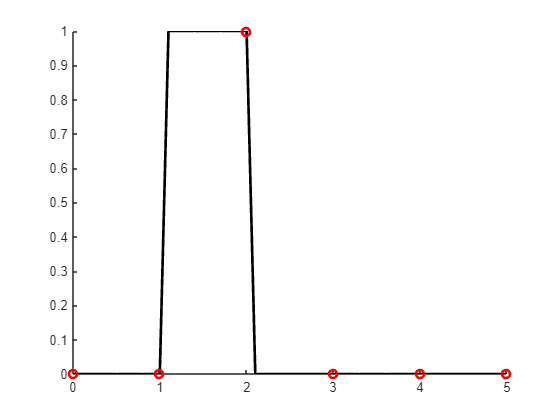

t_vec = 0:Ts/10:5;
u_vec = interp1(ImpulseCurrentProfile.t , ImpulseCurrentProfile.u , t_vec);
u_vec_DT = interp1(ImpulseCurrentProfile.t , ImpulseCurrentProfile.u , ImpulseCurrentProfile_DT.t(1:6));
figure
hold on
plot(t_vec,u_vec,'k','Linewidth',2)
plot(ImpulseCurrentProfile_DT.t(1:6) , u_vec_DT,'ro','Linewidth',2)

### Run Impulse ODE

tspan = t_vec_ode;
SV_IC = zeros(length(A),1);

% Simulation Parameters
Tol.Abs = 1E-7;
Tol.Rel = 1E-7;

options = odeset('RelTol' ,Tol.Rel,      ...
                 'AbsTol' ,Tol.Abs,      ...
                 'MaxStep',(.99)*Ts);

SOLN = ode15s(@(t,x)odeFun(t,x,sys_CT,ImpulseCurrentProfile) , tspan , SV_IC , options);
SOLN_ODE.y = deval(SOLN,t_vec_ode);
SOLN_ODE.x = t_vec_ode;
SOLN_DT.y = deval(SOLN,t_vec_DT);
SOLN_DT.x = t_vec_DT;

#### Test Plot Just Simulated Results

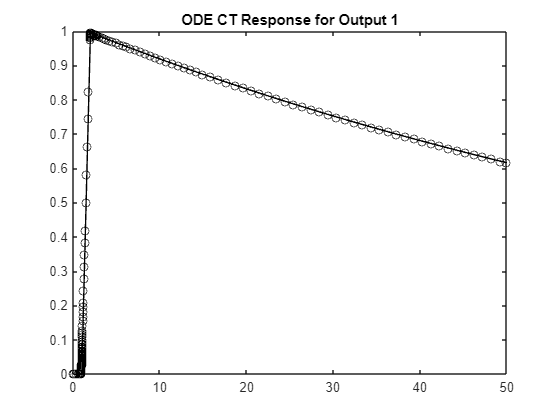

%if 0
figure
plot(SOLN.x,SOLN.y(1,:),'-ok','DisplayName','ODE')
title('ODE CT Response for Output 1')

%end

#### Test Plot DT with CT Simulated

Plots the first 3 and the last

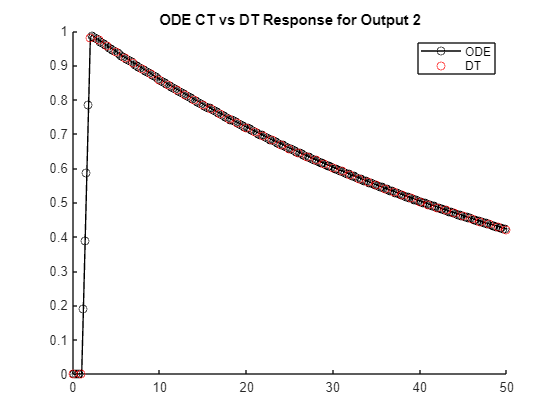

%if 0
figure
hold on
plot(SOLN_ODE.x,SOLN_ODE.y(1,:),'-ok','DisplayName','ODE')
plot(SOLN_DT.x ,SOLN_DT.y(1,:) ,'or' ,'DisplayName','DT')
lgn = legend;
title('ODE CT vs DT Response for Output 1')

figure
hold on
plot(SOLN_ODE.x,SOLN_ODE.y(2,:),'-ok','DisplayName','ODE')
plot(SOLN_DT.x ,SOLN_DT.y(2,:) ,'or' ,'DisplayName','DT')
lgn = legend;
title('ODE CT vs DT Response for Output 2')

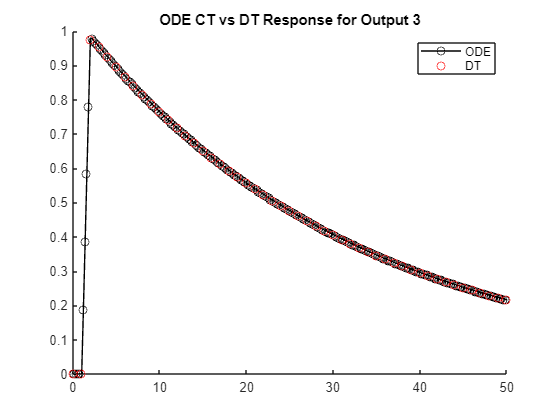


figure
hold on
plot(SOLN_ODE.x,SOLN_ODE.y(3,:),'-ok','DisplayName','ODE')
plot(SOLN_DT.x ,SOLN_DT.y(3,:) ,'or' ,'DisplayName','DT')
lgn = legend;
title('ODE CT vs DT Response for Output 3')

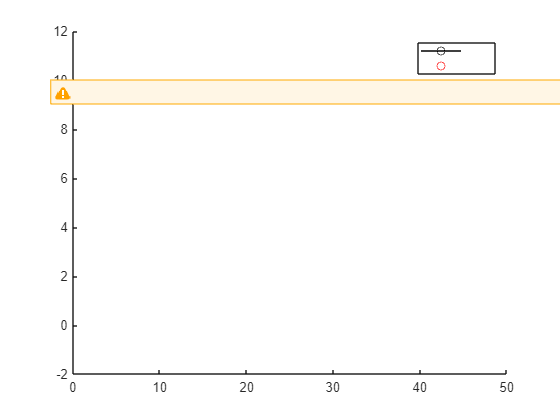


figure
hold on
plot(SOLN_ODE.x,SOLN_ODE.y(end,:),'-ok','DisplayName','ODE')
plot(SOLN_DT.x ,SOLN_DT.y(end,:) ,'or' ,'DisplayName','DT')
lgn = legend;
title('ODE CT vs DT Response for Last Output')

%end

## Perform Ho-Kalman

% max_idx = length(t_final);
% 1;
ImpulseData_All.t = SOLN_ODE.x;
ImpulseData_All.y = SOLN_ODE.y;
ImpulseData = C * SOLN_DT.y;
% [sys_HK] = getHoKalmanROM(ImpulseData_All , ImpulseData , SOLN_DT.x , Ts , N_dominate_dynam , FLAG);

## Start of Ho-Kalman Algorithm

%% Initialize
    if FLAG.Use_t_minus
        start_idx = 1;
    else
        start_idx = 2;
    end
    [N_out,N_steps] = size(ImpulseData);


### Modify Incoming Impulse Data

    %% Sort Data for g_k        
        z_imp    = ImpulseData;
        g_k_temp = z_imp(:,start_idx:end);
        %g_k_temp = z_imp(:,idx_vec(pulse_idx:end));    % t^-
        IC       = z_imp(:,1)

IC =      0
     0
     0
     0
     0
     0


        g_k      = g_k_temp - g_k_temp(:,1)

g_k =          0    0.9851    0.9852    0.9754    0.9657    0.9561    0.9466    0.9372    0.9278    0.9186    0.9095    0.9004    0.8915    0.8826    0.8738    0.8651    0.8565    0.8480    0.8395    0.8312    0.8229    0.8147    0.8066    0.7986    0.7907    0.7828    0.7750    0.7673    0.7597    0.7521    0.7446    0.7372    0.7299    0.7226    0.7154    0.7083    0.7012    0.6943    0.6874    0.6805    0.6738    0.6670    0.6604    0.6538    0.6473    0.6409    0.6345    0.6282    0.6219    0.6158
         0    0.9813    0.9739    0.9567    0.9398    0.9233    0.9070    0.8910    0.8753    0.8599    0.8447    0.8298    0.8152    0.8008    0.7867    0.7729    0.7592    0.7459    0.7327    0.7198    0.7071    0.6946    0.6824    0.6704    0.6586    0.6469    0.6355    0.6243    0.6133    0.6025    0.5919    0.5815    0.5712    0.5612    0.5513    0.5416    0.5320    0.5226    0.5134    0.5044    0.4955    0.4867    0.4782    0.4697    0.4615    0.4533    0.4453    0.4375    0.4298   

        %% Adjust for Order of Magnitude
        disp(['Min of g_k is :' num2str(min(g_k'))])

Min of g_k is :0           0           0           0           0 -3.7707e-08


        disp(['Max of g_k is :' num2str(max(g_k'))])

Max of g_k is :0.98521     0.98134     0.97466     0.96295     0.94257   0.0099999


        switch FLAG.HK_AdjustMag
            case 1 % No Adjustment
                g_k = g_k;
                multiple = eye(N_out);
            case 2 %Simple order of magnitude
%                 Multiple = ones(N_out,1)
%                 for i = 1:N_out
%                     i
%                     min(abs(g_k(i,:))')<0.1 
%                     max(abs(g_k(i,:))')>1
%                     while min(abs(g_k(i,:))')<0.1  max(abs(g_k(i,:))')>1
%                         min_gk = min(abs(g_k(i,:))')';
%                         max_gk = max(abs(g_k(i,:))')';
%                         if min_gk < 0.1
%                             Multiple(i) = Multiple(i)*10;
%                             g_k(i,:) = g_k(i,:)*10;
%                         end
%                         if max_gk > 1
%                             Multiple(i) = Multiple(i)/10;
%                             g_k(i,:) = g_k(i,:)/10;
%                         end
%                     end
%                 end

            case 3
            y_range  = (max(g_k')-min(g_k'));
            g_k      = inv(diag(y_range))*g_k;
            multiple = diag(y_range);
        end
        multiple

multiple =     0.9852         0         0         0         0         0
         0    0.9813         0         0         0         0
         0         0    0.9747         0         0         0
         0         0         0    0.9629         0         0
         0         0         0         0    0.9426         0
         0         0         0         0         0    0.0100


        disp(['Min of g_k is :' num2str(min(g_k'))])

Min of g_k is :0           0           0           0           0 -3.7707e-06


        disp(['Max of g_k is :' num2str(max(g_k'))])

Max of g_k is :1           1           1           1           1           1


%         min_gk = min(g_k')'
%         max_gk = max(g_k')'
        g_k

g_k =          0    0.9999    1.0000    0.9900    0.9802    0.9704    0.9608    0.9512    0.9418    0.9324    0.9231    0.9139    0.9048    0.8958    0.8869    0.8781    0.8694    0.8607    0.8521    0.8437    0.8353    0.8270    0.8187    0.8106    0.8025    0.7945    0.7866    0.7788    0.7711    0.7634    0.7558    0.7483    0.7408    0.7334    0.7261    0.7189    0.7118    0.7047    0.6977    0.6907    0.6839    0.6771    0.6703    0.6637    0.6570    0.6505    0.6440    0.6376    0.6313    0.6250
         0    1.0000    0.9924    0.9749    0.9577    0.9408    0.9242    0.9080    0.8920    0.8762    0.8608    0.8456    0.8307    0.8161    0.8017    0.7876    0.7737    0.7600    0.7466    0.7335    0.7206    0.7079    0.6954    0.6831    0.6711    0.6593    0.6476    0.6362    0.6250    0.6140    0.6032    0.5925    0.5821    0.5718    0.5618    0.5519    0.5421    0.5326    0.5232    0.5140    0.5049    0.4960    0.4873    0.4787    0.4702    0.4619    0.4538    0.4458    0.4379   

        %t_imp = t_impulse(start_idx:end);
        t_imp = SOLN_DT.x(start_idx:end);

### Plot the Impulse Response Data

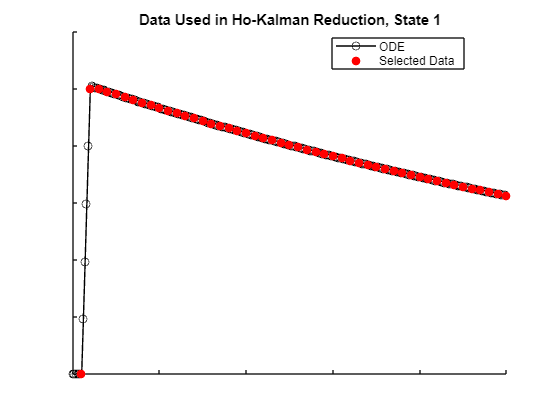

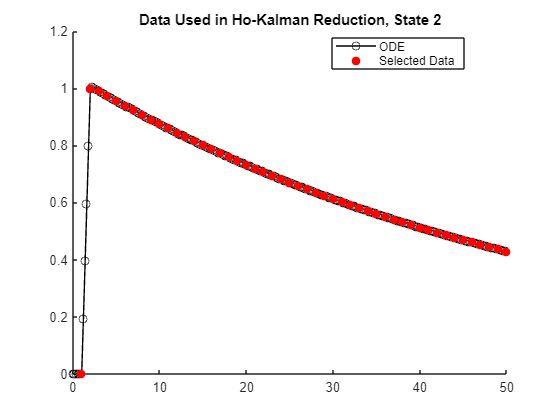

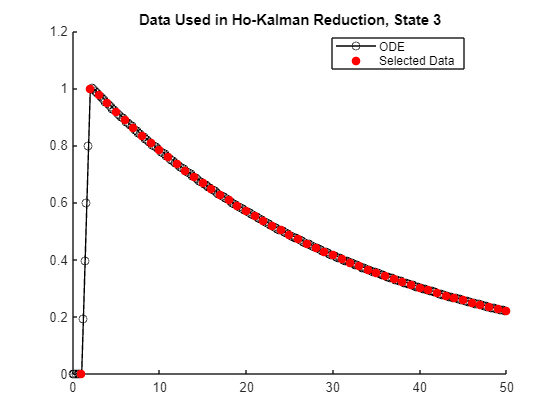

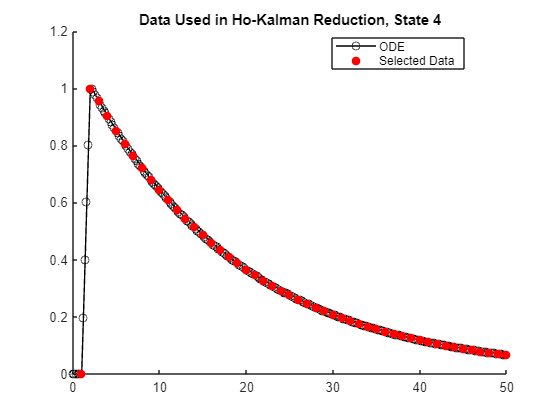

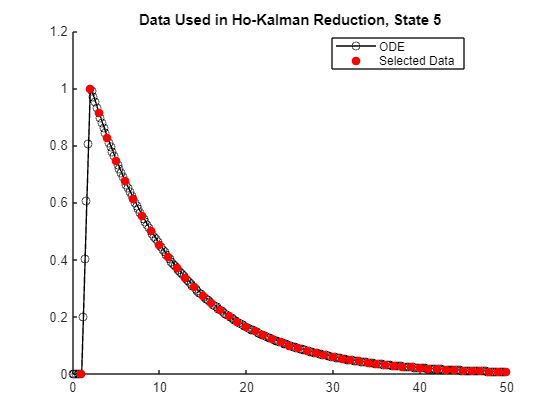

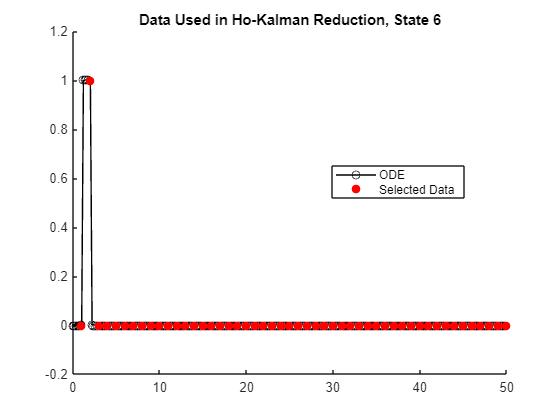

    %% Plot Impulse Response
        if 1
            for i = 1:N_out
            %for i = [1,2,3,10]
                figure
                hold on
                %plot(ImpulseData_All.t , ImpulseData_All.y(i,:) ,'-ok'                      ,'DisplayName','ODE')
                plot(ImpulseData_All.t , ImpulseData_All.y(i,:)/multiple(i,i) ,'-ok'                      ,'DisplayName','ODE')
                plot(t_imp             , g_k(i,:)+IC(i,1)       ,'or' ,'MarkerFaceColor','r','DisplayName','Selected Data')
                %plot(t_imp             , multiple(i,i)*g_k(i,:)+IC(i,1)       ,'or' ,'MarkerFaceColor','r','DisplayName','Selected Data')
                %plot(t_imp(idx_vec(pulse_idx:end),:)  ,g_k(i,:)+IC(i,1),'or','MarkerFaceColor','r') % t^-
                title(['Data Used in Ho-Kalman Reduction, State ' num2str(i)])
                lgn = legend;
                lgn.Location = 'best';
            end
        end

### Zoomed Plot of Impulse Data

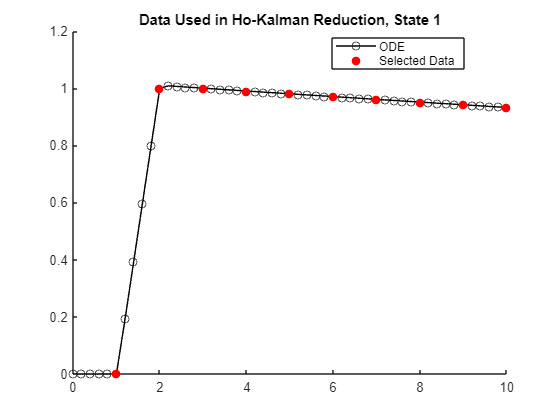

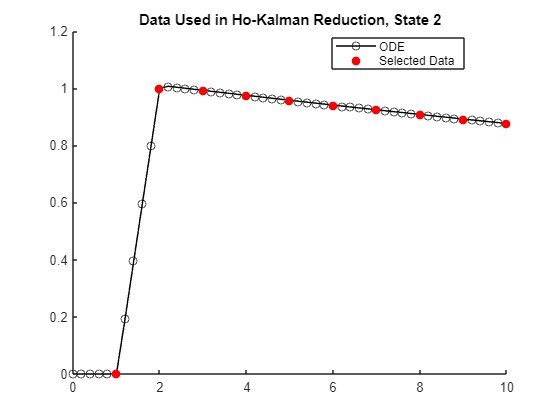

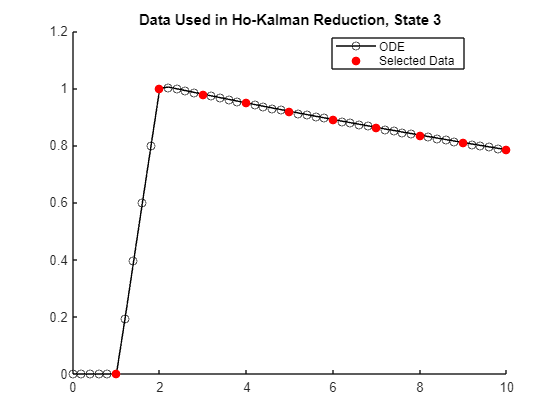

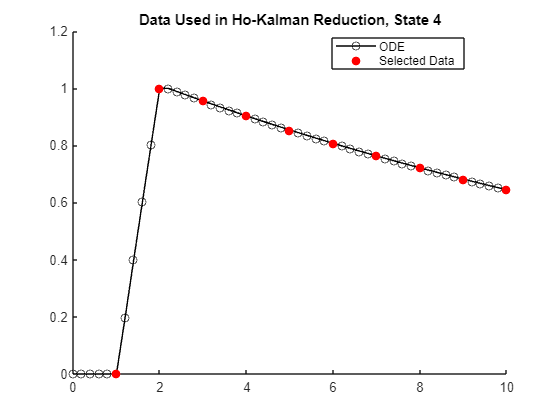

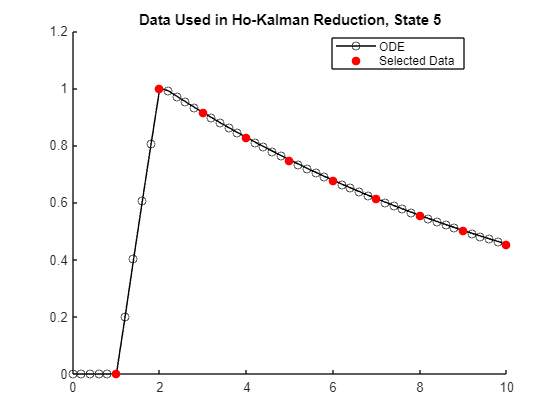

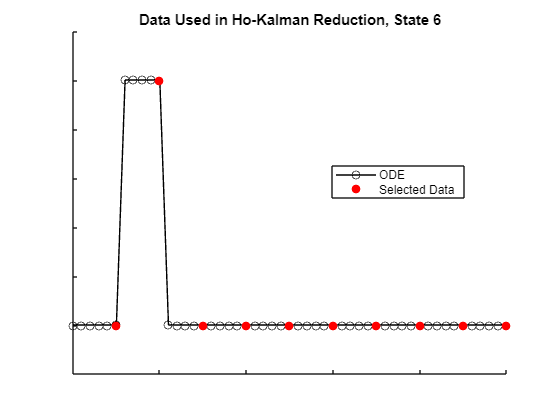

 %% Plot Impulse Response
        if 1
            for i = 1:N_out
            %for i = [1,2,3,10]
                figure
                hold on
                %plot(ImpulseData_All.t , ImpulseData_All.y(i,:) ,'-ok'                      ,'DisplayName','ODE')
                plot(ImpulseData_All.t , ImpulseData_All.y(i,:)/multiple(i,i) ,'-ok'                      ,'DisplayName','ODE')
                plot(t_imp             , g_k(i,:)+IC(i,1)       ,'or' ,'MarkerFaceColor','r','DisplayName','Selected Data')
                %plot(t_imp             , multiple(i,i)*g_k(i,:)+IC(i,1)       ,'or' ,'MarkerFaceColor','r','DisplayName','Selected Data')
                title(['Data Used in Ho-Kalman Reduction, State ' num2str(i)])
                lgn = legend;
                lgn.Location = 'best';
                xlim([0,10])
            end
        end

if FLAG.Use_Ind_ROM
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Get ROM for each desired outputs separately (Combined with Voltage)
%     if N_out > Nrank
%         loop_end = Nrank+1;
%     else
%         loop_end = Nrank;
%     end
    if N_out > N_dominate_dynam
        loop_end = N_dominate_dynam+1; % Only want 1 of the non-dominate dynamics
    else
        loop_end = N_dominate_dynam;
    end

    for OO = 1:loop_end
        %% Get Hankle Matrix
        H = myHankle(g_k(OO,:));


        %% Convert to SS DT sys
        % SVD of Hankle
        [Nrows, Ncolms] = size(H);
        N_outputs = Nrows/Ncolms;
        N_in = 1; %%% !!! Hardcoded but always true for batteries

        [U,S,V] = svd(H);
        switch FLAG.HK_rank
            case 1
                r = rank(S);
            case 2
                r = Ncolms;
            case 3
                r = N_out;
            case 4
                %r = Nrank;
                r = N_dominate_dynam;
        end
        %r = 2;
        r

        %singVals(OO) = S(r,r);

        U_colm = U(:,1:r)
        S_colm = S(1:r,1:r)
        V_colm = V(:,1:r)

        % Balanced Reduction
        S_sqrt = S_colm.^0.5
        obsv_r = U_colm*S_sqrt
        cont_r = S_sqrt*V_colm'

        % C_r
        C_r = obsv_r(1:N_outputs,:   )
        C_r = multiple(OO,OO) * C_r

        % B_r
        B_r = cont_r(:        ,N_in)

        % A_r
        PP   = obsv_r(1:end-N_outputs,:)
        PP_p = obsv_r(N_outputs+1:end,:)
        threshold = 1e-7;
        PP_inv = pinv(PP,threshold)
        A_r = PP_inv*PP_p

        % D_r ~ !!!!! I'm assuming this is correct
        D_r = zeros(N_outputs,N_in)

%             if FLAG.PlotSingVal
%                 figure
%                 semilogy(1:1:length(diag(S)) , diag(S),'-k','Linewidth',2)
%                 xlim([0,length(diag(S))])
%                 ylabel('Singular Values')
%                 title([RESULTS.Labels.title{OO} ' Singular Values of \Sigma for Hankel'])
%             end


        %% Return the system
        sys_HK{OO} = ss(A_r, B_r, C_r, D_r, Ts);
    end

else
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %% Get ROM for all desired outputs combined
            %% Get Hankle Matrix
            H = myHankle(g_k)
    
    
            %% Convert to SS DT sys
            % SVD of Hankle
            [Nrows, Ncolms] = size(H);
            N_outputs = Nrows/Ncolms;
            N_in = 1; %%% !!! Hardcoded but always true for batteries
    
            [U,S,V] = svd(H);
            switch FLAG.HK_rank
                case 1
                    r = rank(S);
                case 2
                    r = Ncolms;
                case 3
                    r = N_out;
                case 4
                    r = Nrank;
            end
            r
            
            %singVals = S(r,r)
    
            U_colm = U(:,1:r)
            S_colm = S(1:r,1:r)
            V_colm = V(:,1:r)
    
            % Balanced Reduction
            S_sqrt = S_colm.^0.5
            obsv_r = U_colm*S_sqrt
            cont_r = S_sqrt*V_colm'    

            % C_r

H =          0    0.9999    1.0000    0.9900    0.9802    0.9704    0.9608    0.9512    0.9418    0.9324    0.9231    0.9139    0.9048    0.8958    0.8869    0.8781    0.8694    0.8607    0.8521    0.8437    0.8353    0.8270    0.8187    0.8106    0.8025
         0    1.0000    0.9924    0.9749    0.9577    0.9408    0.9242    0.9080    0.8920    0.8762    0.8608    0.8456    0.8307    0.8161    0.8017    0.7876    0.7737    0.7600    0.7466    0.7335    0.7206    0.7079    0.6954    0.6831    0.6711
         0    1.0000    0.9788    0.9483    0.9188    0.8902    0.8625    0.8357    0.8097    0.7845    0.7600    0.7364    0.7135    0.6912    0.6697    0.6489    0.6287    0.6091    0.5902    0.5718    0.5540    0.5367    0.5200    0.5038    0.4882
         0    1.0000    0.9551    0.9029    0.8535    0.8069    0.7627    0.7210    0.6816    0.6443    0.6091    0.5758    0.5443    0.5145    0.4864    0.4598    0.4347    0.4109    0.3884    0.3672    0.3471    0.3281    0.3102    0.2932   

r = 25

U_colm =    -0.1357    0.2143   -0.3457    0.0100    0.1087   -0.0816    0.0630    0.1318   -0.0632   -0.0984   -0.0367   -0.0366   -0.0453    0.0299    0.0311   -0.0103    0.0029   -0.0029   -0.0323    0.0030    0.0676   -0.0954   -0.1347   -0.0873   -0.0083
   -0.1258    0.1504   -0.3675    0.0418   -0.0159    0.1077   -0.1664    0.1313   -0.0634   -0.0978   -0.0366   -0.0364   -0.0458    0.0294    0.0317   -0.0095    0.0027   -0.0035   -0.0292    0.0046    0.0680   -0.0898   -0.1267   -0.0755   -0.0204
   -0.1106    0.0581   -0.3957    0.0750   -0.1205    0.0952    0.1723    0.1244   -0.0639   -0.0922   -0.0352   -0.0347   -0.0490    0.0270    0.0361   -0.0069   -0.0009   -0.0067   -0.0044    0.0158    0.0512   -0.0387   -0.0513    0.0172   -0.0862
   -0.0898   -0.0553   -0.4219    0.0826   -0.0722   -0.2313   -0.0874    0.0623   -0.0521   -0.0416   -0.0194   -0.0208   -0.0528    0.0173    0.0530   -0.0115   -0.0233   -0.0101    0.1370   -0.0369   -0.2459    0.3342    0.4410    0.29

S_colm =    31.5611         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    3.8961         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    2.1870         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.8795         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

V_colm =    -0.2414   -0.4696    0.8488   -0.0269   -0.0047   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000
   -0.2522   -0.3511   -0.2932   -0.8511   -0.0521   -0.0001   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
   -0.2457   -0.2710   -0.2101    0.2294    0.4510    0.4115    0.3715    0.3836    0.1838   -0.2004    0.0853   -0.0920    0.1177    0.0741   -0.0397   -0.0265    0.0115    0.0027   -0.0055   -0.0015    0.0005    0.0007    0.0003   -0.0002    0.0001
   -0.2396   -0.2193   -0.1814    0.2073    0.2719    0.1100   -0.0478   -0.2697   -0.2328    0.4756   -0.3624    0.3599   -0.3065   -0.1181    0.0357    0.0593   -0.0590   -0.0024    0.0055    0.0084   -0.0060   -0.0047   -0.0015    0.00

S_sqrt =     5.6179         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.9739         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.4788         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.9378         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

obsv_r =    -0.7625    0.4231   -0.5112    0.0094    0.0565   -0.0088    0.0009    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.7066    0.2969   -0.5434    0.0392   -0.0083    0.0117   -0.0023    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.6212    0.1147   -0.5852    0.0703   -0.0627    0.0103    0.0024    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
   -0.5043   -0.1091   -0.6240    0.0774   -0.0375   -0.0251   -0.0012    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.00

cont_r =    -1.3563   -1.4170   -1.3805   -1.3460   -1.3130   -1.2813   -1.2510   -1.2218   -1.1938   -1.1668   -1.1408   -1.1158   -1.0917   -1.0684   -1.0459   -1.0242   -1.0032   -0.9829   -0.9632   -0.9442   -0.9257   -0.9078   -0.8904   -0.8736   -0.8572
   -0.9269   -0.6931   -0.5350   -0.4330   -0.3395   -0.2538   -0.1754   -0.1035   -0.0377    0.0226    0.0778    0.1284    0.1746    0.2169    0.2556    0.2909    0.3231    0.3526    0.3794    0.4038    0.4261    0.4463    0.4646    0.4811    0.4961
    1.2553   -0.4336   -0.3106   -0.2683   -0.2293   -0.1933   -0.1602   -0.1297   -0.1016   -0.0757   -0.0518   -0.0298   -0.0095    0.0092    0.0265    0.0424    0.0570    0.0705    0.0829    0.0944    0.1049    0.1146    0.1235    0.1317    0.1392
   -0.0252   -0.7982    0.2151    0.1944    0.1743    0.1548    0.1358    0.1175    0.0997    0.0825    0.0660    0.0500    0.0347    0.0199    0.0058   -0.0078   -0.0208   -0.0333   -0.0452   -0.0566   -0.0675   -0.0778   -0.0877   -0.09

C_r =    -0.7625    0.4231   -0.5112    0.0094    0.0565   -0.0088    0.0009    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.7066    0.2969   -0.5434    0.0392   -0.0083    0.0117   -0.0023    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.6212    0.1147   -0.5852    0.0703   -0.0627    0.0103    0.0024    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
   -0.5043   -0.1091   -0.6240    0.0774   -0.0375   -0.0251   -0.0012    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000 

B_r =    -1.3563
   -0.9269
    1.2553
   -0.0252
   -0.0025
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000


PP =    -0.7625    0.4231   -0.5112    0.0094    0.0565   -0.0088    0.0009    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.7066    0.2969   -0.5434    0.0392   -0.0083    0.0117   -0.0023    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.6212    0.1147   -0.5852    0.0703   -0.0627    0.0103    0.0024    0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
   -0.5043   -0.1091   -0.6240    0.0774   -0.0375   -0.0251   -0.0012    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000  

PP_p =    -0.7984    0.1792    0.0658   -0.0285    0.0458   -0.0088    0.0009   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
   -0.7375    0.0520    0.0381    0.0008   -0.0183    0.0114   -0.0023   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.6452   -0.1285    0.0051    0.0304   -0.0708    0.0099    0.0023   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000
   -0.5202   -0.3428   -0.0178    0.0356   -0.0456   -0.0238   -0.0012   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

PP_inv = 1.0e+05 *

   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.000

A_r =     0.9818    0.0165   -0.0559    0.0026    0.0009    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000
   -0.0561    0.9048    0.0544   -0.0454    0.0016   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0501    0.3766   -0.0136   -0.0198    0.0105    0.0000    0.0000    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
   -0.0005   -0.0010   -0.6357    0.0808   -0.0923   -0.0005    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000 

            C_r = obsv_r(1:N_outputs,:   )
            C_r = multiple * C_r;


$$\mathcal{C}=\left\lbrack \begin{array}{cccc}
B & \mathrm{AB} & \cdots  & A^{N-1} B
\end{array}\right\rbrack$$

$$\$$


            % B_r
            B_r = cont_r(:        ,1:N_in)

$\mathrm{PP}=\left\lbrack \begin{array}{c}
C\\
\mathrm{CA}\\
\vdots \\
{\mathrm{CA}}^{N-2} 
\end{array}\right\rbrack \;$, ${\mathrm{PP}}_p =\left\lbrack \begin{array}{c}
\mathrm{CA}\\
{\mathrm{CA}}^2 \\
\vdots \\
{\mathrm{CA}}^{N-1} 
\end{array}\right\rbrack$


$$\mathrm{PP}*A={\mathrm{PP}}_p$$



$$A={\textrm{PP}}^{-1} {\textrm{PP}}_p$$


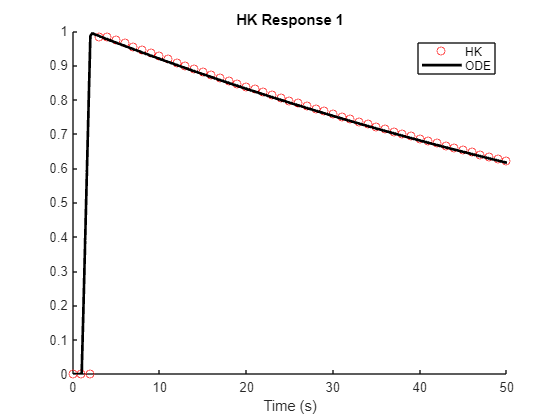

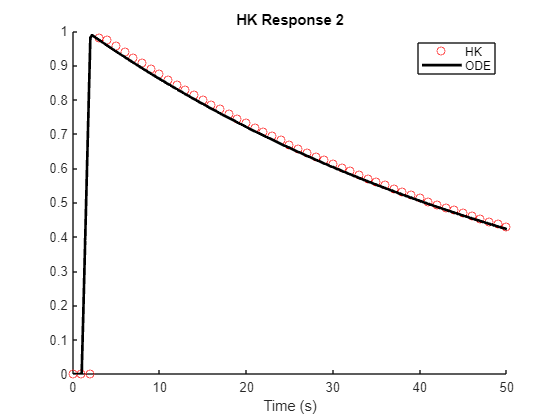

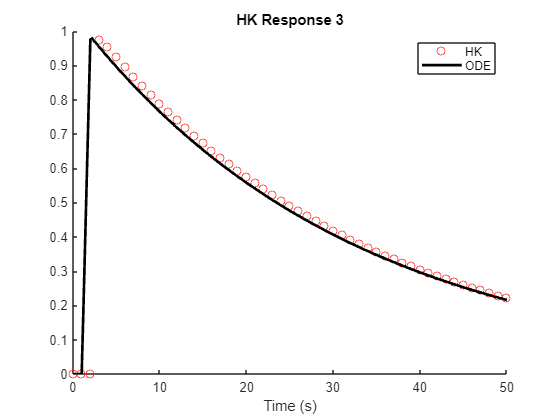

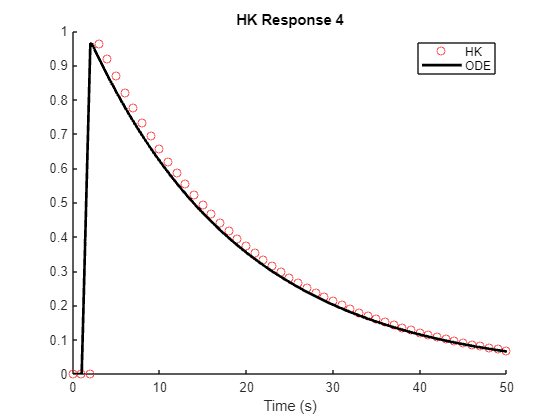

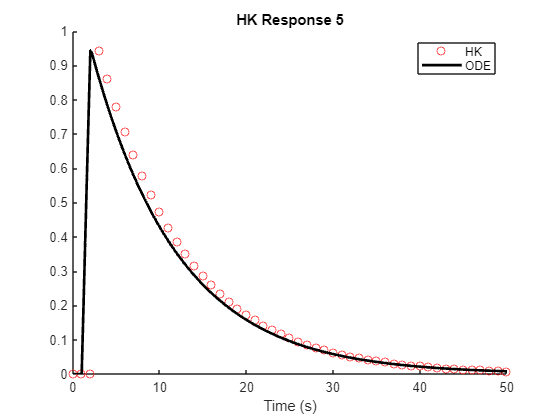

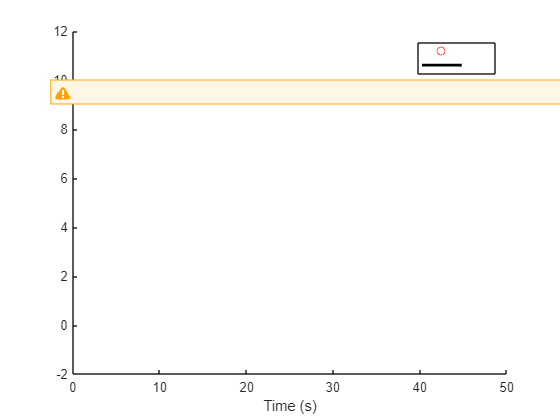

            % A_r
            PP   = obsv_r(1:end-N_outputs,:)
            PP_p = obsv_r(N_outputs+1:end,:)
            threshold = 1e-7;
            PP_inv = pinv(PP,threshold)
            A_r = PP_inv*PP_p
    
            % D_r ~ !!!!! I'm assuming this is correct
            D_r = zeros(N_outputs,N_in);
    
            if 0
                figure
                semilogy(1:1:length(diag(S)) , diag(S),'-k','Linewidth',2)
                xlim([0,length(diag(S))])
                ylabel('Singular Values')
                title('All ROM Singular Values of \Sigma for Hankel')
            end
    
    
            %% Return the system
            sys_HK = ss(A_r, B_r, C_r, D_r, Ts);
%             sys{1 , end+1} = ss(A_r, B_r, C_r, D_r, Ts);
%             sys = ss(A_r, B_r, C_r, D_r, Ts);

end
if FLAG.Use_Ind_ROM
    for i = 1:length(sys_HK)%-1
        sys_HK_CT{i} = d2c(sys_HK{i},'tustin'); %'matched'

    end
else

Eigenvalue Comparison


    sys_HK_CT = d2c(sys_HK,'tustin'); %'matched'

---------------------


end

Eig(A_DT)


## Analysis of HK

if FLAG.Use_Ind_ROM

3.7201e-44
   0.90484
   0.94532
   0.96887
   0.98237
   0.99005


    for i = 1:length(sys_HK)%-1
        [eig_vec_HK_DT{i}, eig_val_HK_DT{i}] = eig(sys_HK{i}.A);
        [eig_vec_HK_CT{i}, eig_val_HK_CT{i}] = eig(sys_HK_CT{i}.A);
        eig_val_HK_DT_diag{i} = real(diag(eig_val_HK_DT{i}));
        eig_val_HK_CT_diag{i} = real(diag(eig_val_HK_CT{i}));
        [U_HK_DT,S_HK_DT{i},V_HK_DT] = svd(sys_HK{i}.A);
        [U_HK_CT,S_HK_CT{i},V_HK_CT] = svd(sys_HK_CT{i}.A);
    end

-0.62375+0.12225i               0+0i                     0+0i                     0+0i                     0+0i                     0+0i                      0+0i                     0+0i                    0+0i                     0+0i                           0+0i                     0+0i               0+0i                     0+0i                     0+0i                     0+0i                     0+0i                     0+0i                      0+0i                     0+0i                          0+0i                     0+0i                     0+0i                     0+0i                     0+0i
       0+0i              -0.62375-0.12225i               0+0i                     0+0i                     0+0i                     0+0i                      0+0i                     0+0i                    0+0i                     0+0i                           0+0i                     0+0i               0+0i                     0+0i                     0+0i                     

else
    [eig_vec_HK_DT, eig_val_HK_DT] = eig(sys_HK.A);
    [eig_vec_HK_CT, eig_val_HK_CT] = eig(sys_HK_CT.A);
    eig_val_HK_DT_diag = real(diag(eig_val_HK_DT));
    eig_val_HK_CT_diag = real(diag(eig_val_HK_CT));
    [U_HK_DT,S_HK_DT,V_HK_DT] = svd(sys_HK.A);
    [U_HK_CT,S_HK_CT,V_HK_CT] = svd(sys_HK_CT.A);
end

## Get Response

Calls lsim using the ROM generated by HK algorithm

if FLAG.Use_Ind_ROM
    for i = 1:length(sys_HK)%-1
        x_red = zeros(length(sys_HK{i}.A),1);
        [z_soln_HK_DT{i} , t_soln_HK_DT{i} , x_soln_HK_DT{i}] = lsim(sys_HK{i}, ImpulseCurrentProfile_DT.u , ImpulseCurrentProfile_DT.t , x_red);
    end
else
    x_red = zeros(length(sys_HK.A),1);
    %[z_soln_HK_DT{1} , t_soln_HK_DT{1} , x_soln_HK_DT{1}] = lsim(sys_HK{end}, ImpulseCurrentProfile_DT.u , ImpulseCurrentProfile_DT.t , x_red)
    [z_soln_HK_DT , t_soln_HK_DT , x_soln_HK_DT] = lsim(sys_HK, ImpulseCurrentProfile_DT.u , ImpulseCurrentProfile_DT.t , x_red);
end

## Plot HK Response

z_ODE = C*SOLN_ODE.y;
for i = 1:6
    figure
    hold on
    if FLAG.Use_Ind_ROM
        plot(t_soln_HK_DT{i} , z_soln_HK_DT{i}(:,1),'or'  , 'DisplayName','HK')
    else
        plot(t_soln_HK_DT , z_soln_HK_DT(:,i),'or'  , 'DisplayName','HK')
        %plot(t_soln_HK_DT , multiple(i,i)*z_soln_HK_DT(:,i),'or'  , 'DisplayName','HK')
    end
    plot(t_vec_ode    , z_ODE(i,:)       ,'-k' , 'DisplayName','ODE','Linewidth',2)
    xlabel('Time (s)')
    title(['HK Response ' num2str(i)])
    lgn = legend;
    xlim([0,50])
end

## Print Response

disp('Eigenvalue Comparison')
disp('---------------------')
disp('Eig(A_DT)')
disp(num2str(diag(eig_val_DT(end-5:end,end-5:end))))
if FLAG.Use_Ind_ROM
    for i = 1:6
        disp(['HK System, Variable ' num2str(i)])
        disp(num2str(eig_val_HK_DT{i}))
    end
else
    disp(num2str(eig_val_HK_DT))
end

## ODE Function

function [xdot] = odeFun(t,x,sys,currentProfile)
    % get current
    u = interp1(currentProfile.t , currentProfile.u , t); 
    
    % get xdot
    xdot = sys.A * x + sys.B * u;
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Get Ho-Kalman ROM
function [sys] = getHoKalmanROM(ImpulseData_All,  ImpulseData , t_impulse , Ts , Nrank , FLAG)  
%     %% Initialize
%     if FLAG.Use_t_minus
%         start_idx = 1;
%     else
%         start_idx = 2;
%     end
%     [N_out,N_steps] = size(ImpulseData);
% 
% 
%     %% Sort Data for g_k        
%         z_imp    = ImpulseData;
%         g_k_temp = z_imp(:,start_idx:end);
%         %g_k_temp = z_imp(:,idx_vec(pulse_idx:end));    % t^-
%         IC       = z_imp(:,1);
%         g_k      = g_k_temp - g_k_temp(:,1);
%     
%         t_imp = t_impulse(start_idx:end);
%         
%     
%     %% Plot Impulse Response
%         if 1
%             for i = 1:N_out
%             %for i = [1,2,3,10]
%                 figure
%                 hold on
%                 plot(ImpulseData_All.t , ImpulseData_All.y(i,:) ,'-ok'                      ,'DisplayName','ODE')
%                 plot(t_imp             , g_k(i,:)+IC(i,1)       ,'or' ,'MarkerFaceColor','r','DisplayName','Selected Data')
%                 %plot(t_imp(idx_vec(pulse_idx:end),:)  ,g_k(i,:)+IC(i,1),'or','MarkerFaceColor','r') % t^-
%                 title(['Data Used in Ho-Kalman Reduction, State ' num2str(i)])
%                 lgn = legend;
%                 lgn.Location = 'best';
%             end
%         end
% 
% if FLAG.Use_Ind_ROM
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %% Get ROM for each desired outputs separately (Combined with Voltage)
%     if N_out > Nrank
%         loop_end = Nrank+1;
%     else
%         loop_end = Nrank;
%     end
% 
%         for OO = 1:loop_end
%             %% Get Hankle Matrix
%             H = myHankle(g_k(OO,:));
%     
%     
%             %% Convert to SS DT sys
%             % SVD of Hankle
%             [Nrows, Ncolms] = size(H);
%             N_outputs = Nrows/Ncolms;
%             N_in = 1; %%% !!! Hardcoded but always true for batteries
%     
%             [U,S,V] = svd(H);
%             switch FLAG.HK_rank
%                 case 1
%                     r = rank(S);
%                 case 2
%                     r = Ncolms;
%                 case 3
%                     r = N_out;
%                 case 4
%                     r = Nrank;
%             end
%             r = 2;
%             r
% 
%             %singVals(OO) = S(r,r);
%     
%             U_colm = U(:,1:r);
%             S_colm = S(1:r,1:r);
%             V_colm = V(:,1:r);
%     
%             % Balanced Reduction
%             S_sqrt = S_colm.^0.5;
%             obsv_r = U_colm*S_sqrt;
%             cont_r = S_sqrt*V_colm';
%     
%             % C_r
%             C_r = obsv_r(1:N_outputs,:   );
%     
%             % B_r
%             B_r = cont_r(:        ,N_in);
%     
%             % A_r
%             PP   = obsv_r(1:end-N_outputs,:);
%             PP_p = obsv_r(N_outputs+1:end,:);
%             threshold = 1e-7;
%             PP_inv = pinv(PP,threshold);
%             A_r = PP_inv*PP_p;
%     
%             % D_r ~ !!!!! I'm assuming this is correct
%             D_r = zeros(N_outputs,N_in);
% 
% %             if FLAG.PlotSingVal
% %                 figure
% %                 semilogy(1:1:length(diag(S)) , diag(S),'-k','Linewidth',2)
% %                 xlim([0,length(diag(S))])
% %                 ylabel('Singular Values')
% %                 title([RESULTS.Labels.title{OO} ' Singular Values of \Sigma for Hankel'])
% %             end
%     
%     
%             %% Return the system
%             sys{OO} = ss(A_r, B_r, C_r, D_r, Ts);
%         end
% 
% else
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     %% Get ROM for all desired outputs combined
%             %% Get Hankle Matrix
%             H = myHankle(g_k);
%     
%     
%             %% Convert to SS DT sys
%             % SVD of Hankle
%             [Nrows, Ncolms] = size(H);
%             N_outputs = Nrows/Ncolms;
%             N_in = 1; %%% !!! Hardcoded but always true for batteries
%     
%             [U,S,V] = svd(H);
%             switch FLAG.HK_rank
%                 case 1
%                     r = rank(S);
%                 case 2
%                     r = Ncolms;
%                 case 3
%                     r = N_out;
%                 case 4
%                     r = Nrank;
%             end
%             r
%             
%             %singVals = S(r,r)
%     
%             U_colm = U(:,1:r);
%             S_colm = S(1:r,1:r);
%             V_colm = V(:,1:r);
%     
%             % Balanced Reduction
%             S_sqrt = S_colm.^0.5;
%             obsv_r = U_colm*S_sqrt;
%             cont_r = S_sqrt*V_colm';
%     
%             % C_r
%             C_r = obsv_r(1:N_outputs,:   );
%     
%             % B_r
%             B_r = cont_r(:        ,N_in);
%     
%             % A_r
%             PP   = obsv_r(1:end-N_outputs,:);
%             PP_p = obsv_r(N_outputs+1:end,:);
%             threshold = 1e-7;
%             PP_inv = pinv(PP,threshold);
%             A_r = PP_inv*PP_p;
%     
%             % D_r ~ !!!!! I'm assuming this is correct
%             D_r = zeros(N_outputs,N_in);
%     
%             if 1
%                 figure
%                 semilogy(1:1:length(diag(S)) , diag(S),'-k','Linewidth',2)
%                 xlim([0,length(diag(S))])
%                 ylabel('Singular Values')
%                 title('All ROM Singular Values of \Sigma for Hankel')
%             end
%     
%     
%             %% Return the system
%             sys{1} = ss(A_r, B_r, C_r, D_r, Ts);
% %             sys{1 , end+1} = ss(A_r, B_r, C_r, D_r, Ts);
% %             sys = ss(A_r, B_r, C_r, D_r, Ts);
% 
% end
end